% Walking Robot -- DDPG Agent Training Script (3D)
% Copyright 2019 The MathWorks, Inc.

%% SET UP ENVIRONMENT
% Speedup options
useFastRestart = true;
useGPU = false;
useParallel = false;

% Create the observation info
numObs = 45;
observationInfo = rlNumericSpec([numObs 1]);
observationInfo.Name = 'observations';

% create the action info
numAct = 12;
actionInfo = rlNumericSpec([numAct 1],'LowerLimit',-1,'UpperLimit', 1);
actionInfo.Name = 'foot_position';

% Environment
mdl = 'biped_RL';
open_system(mdl);
blk = [mdl,'/RL Agent'];
env = rlSimulinkEnv(mdl,blk,observationInfo,actionInfo);
env.ResetFcn = @(in)walkerResetFcn(in,upper_leg_length/100,lower_leg_length/100,h/100,'3D');
if ~useFastRestart
   env.UseFastRestart = 'off';
end

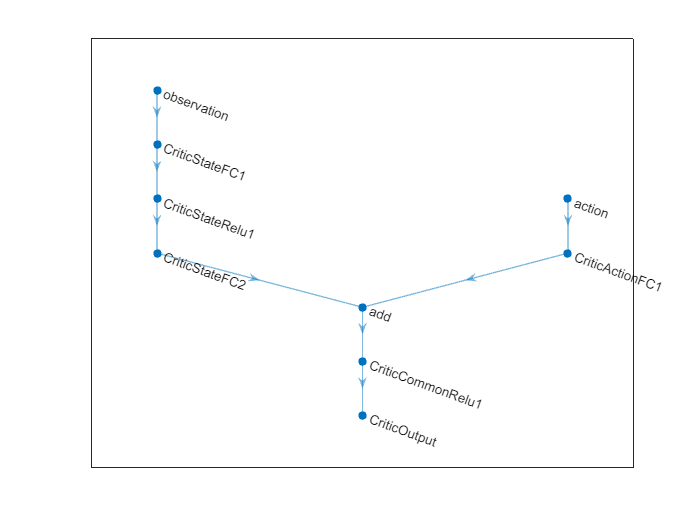


%% CREATE NEURAL NETWORKS createDDPGNetworks;
%% CRITIC
% Create the critic network layers
criticLayerSizes = [400 300];
statePath = [
    imageInputLayer([numObs 1 1],'Normalization','none','Name', 'observation')
    fullyConnectedLayer(criticLayerSizes(1), 'Name', 'CriticStateFC1', ... 
            'Weights',2/sqrt(numObs)*(rand(criticLayerSizes(1),numObs)-0.5), ...
            'Bias',2/sqrt(numObs)*(rand(criticLayerSizes(1),1)-0.5))
    reluLayer('Name','CriticStateRelu1')
    fullyConnectedLayer(criticLayerSizes(2), 'Name', 'CriticStateFC2', ...
            'Weights',2/sqrt(criticLayerSizes(1))*(rand(criticLayerSizes(2),criticLayerSizes(1))-0.5), ... 
            'Bias',2/sqrt(criticLayerSizes(1))*(rand(criticLayerSizes(2),1)-0.5))
    ];
actionPath = [
    imageInputLayer([numAct 1 1],'Normalization','none', 'Name', 'action')
    fullyConnectedLayer(criticLayerSizes(2), 'Name', 'CriticActionFC1', ...
            'Weights',2/sqrt(numAct)*(rand(criticLayerSizes(2),numAct)-0.5), ... 
            'Bias',2/sqrt(numAct)*(rand(criticLayerSizes(2),1)-0.5))
    ];
commonPath = [
    additionLayer(2,'Name','add')
    reluLayer('Name','CriticCommonRelu1')
    fullyConnectedLayer(1, 'Name', 'CriticOutput',...
            'Weights',2*5e-3*(rand(1,criticLayerSizes(2))-0.5), ...
            'Bias',2*5e-3*(rand(1,1)-0.5))
    ];

% Connect the layer graph
criticNetwork = layerGraph(statePath);
criticNetwork = addLayers(criticNetwork, actionPath);
criticNetwork = addLayers(criticNetwork, commonPath);
criticNetwork = connectLayers(criticNetwork,'CriticStateFC2','add/in1');
criticNetwork = connectLayers(criticNetwork,'CriticActionFC1','add/in2');

plot(criticNetwork)

% 
% criticNetwork = initialize(criticNetwork);
% summary(criticNetwork);

% Create critic representation
criticOptions = rlRepresentationOptions('Optimizer','adam','LearnRate',1e-3, ... 
                                        'GradientThreshold',1,'L2RegularizationFactor',2e-4);
if useGPU
   criticOptions.UseDevice = 'gpu'; 
end
critic = rlQValueFunction(criticNetwork, observationInfo, actionInfo, 'Observation', 'Action');



%% ACTOR
% Create the actor network layers
actorLayerSizes = [400 300];
actorNetwork = [
    imageInputLayer([numObs 1 1],'Normalization','none','Name','observation')
    fullyConnectedLayer(actorLayerSizes(1), 'Name', 'ActorFC1', ...
            'Weights',2/sqrt(numObs)*(rand(actorLayerSizes(1),numObs)-0.5), ... 
            'Bias',2/sqrt(numObs)*(rand(actorLayerSizes(1),1)-0.5))
    reluLayer('Name', 'ActorRelu1')
    fullyConnectedLayer(actorLayerSizes(2), 'Name', 'ActorFC2', ... 
            'Weights',2/sqrt(actorLayerSizes(1))*(rand(actorLayerSizes(2),actorLayerSizes(1))-0.5), ... 
            'Bias',2/sqrt(actorLayerSizes(1))*(rand(actorLayerSizes(2),1)-0.5))
    reluLayer('Name', 'ActorRelu2')
    fullyConnectedLayer(numAct, 'Name', 'ActorFC3', ... 
            'Weights',2*5e-3*(rand(numAct,actorLayerSizes(2))-0.5), ... 
            'Bias',2*5e-3*(rand(numAct,1)-0.5))                       
    tanhLayer('Name','ActorTanh1')
    ];

% Create actor representation using rlDeterministicActorRepresentation
actorOptions = rlRepresentationOptions('Optimizer','adam','LearnRate',1e-4, ...
                                       'GradientThreshold',1,'L2RegularizationFactor',1e-5);
if useGPU
   actorOptions.UseDevice = 'gpu'; 
end
actor = rlContinuousDeterministicActor(actorNetwork, observationInfo, actionInfo);

%% CREATE AND TRAIN AGENT  createDDPGOptions;
%% DDPG Agent Options
agentOptions = rlDDPGAgentOptions;
agentOptions.SampleTime = Ts;
agentOptions.DiscountFactor = 0.99;
agentOptions.MiniBatchSize = 128;
agentOptions.ExperienceBufferLength = 5e5;
agentOptions.TargetSmoothFactor = 1e-3;
agentOptions.NoiseOptions.MeanAttractionConstant = 5;
agentOptions.NoiseOptions.Variance = 0.5;
agentOptions.NoiseOptions.VarianceDecayRate = 1e-5;

%% Training Options
trainingOptions = rlTrainingOptions;
trainingOptions.MaxEpisodes = 5000;
trainingOptions.MaxStepsPerEpisode = Tf/Ts;
trainingOptions.ScoreAveragingWindowLength = 100;
trainingOptions.StopTrainingCriteria = 'AverageReward';
trainingOptions.StopTrainingValue = 110;
trainingOptions.SaveAgentCriteria = 'EpisodeReward';
trainingOptions.SaveAgentValue = 150;
trainingOptions.Plots = 'training-progress';
trainingOptions.Verbose = true;
if useParallel
    trainingOptions.Parallelization = 'async';
    trainingOptions.ParallelizationOptions.StepsUntilDataIsSent = 32;
end

agent = rlDDPGAgent(actor,critic,agentOptions);
trainingResults = train(agent,env,trainingOptions);

Episode:   1/5000 | Episode reward:    -4.45 | Episode steps:   12 | Average reward:    -4.45 | Step Count:   12 | Episode Q0:    -0.00
Episode:   2/5000 | Episode reward:    -4.43 | Episode steps:   18 | Average reward:    -4.44 | Step Count:   30 | Episode Q0:    -0.00
Episode:   3/5000 | Episode reward:    -3.26 | Episode steps:    8 | Average reward:    -4.05 | Step Count:   38 | Episode Q0:    -0.00
Episode:   4/5000 | Episode reward:    -3.28 | Episode steps:   10 | Average reward:    -3.86 | Step Count:   48 | Episode Q0:    -0.00
Episode:   5/5000 | Episode reward:    -2.34 | Episode steps:   19 | Average reward:    -3.55 | Step Count:   67 | Episode Q0:    -0.00
Episode:   6/5000 | Episode reward:    -2.30 | Episode steps:   12 | Average reward:    -3.34 | Step Count:   79 | Episode Q0:    -0.00
Episode:   7/5000 | Episode reward:    -5.97 | Episode steps:   13 | Average reward:    -3.72 | Step Count:   92 | Episode Q0:    -0.00
Episode:   8/5000 | Episode reward:   -10.40 | E

Episode:  20/5000 | Episode reward:    -0.27 | Episode steps:    1 | Average reward:    -2.19 | Step Count:  151 | Episode Q0:    -0.25



%% SAVE AGENT
reset(agent); % Clears the experience buffer
curDir = pwd;
saveDir = 'savedAgents';
cd(saveDir)
save(['trainedAgent_3D_' datestr(now,'mm_DD_YYYY_HHMM')],'agent');
save(['trainingResults_3D_' datestr(now,'mm_DD_YYYY_HHMM')],'trainingResults');
cd(curDir)